% Input sequence
x = input('Enter the sequence: ');
% Number of points
N = input('Enter the Point: ');
n = length(x);
x = [x zeros(1, N - n)];

% Bit-reverse ordering
y = bitrevorder(x);

% Calculate the DFT using Cooley-Tukey algorithm
M = log2(N);
for m = 1:M
    d = 2^m;
    for l = 1:d:N - d + 1
        for k = 0:(d/2) - 1
            w = exp(-1i * 2 * pi * k / d);
            z1 = y(l + k);
            z2 = y(l + k + d/2);
            y(l + k) = z1 + w * z2;
            y(l + k + d/2) = z1 - w * z2;
        end
    end
end

% Display the DFT result
disp(y);

  20.0000 + 0.0000i  -5.8284 - 2.4142i   0.0000 + 0.0000i  -0.1716 - 0.4142i   0.0000 + 0.0000i  -0.1716 + 0.4142i   0.0000 + 0.0000i  -5.8284 + 2.4142i



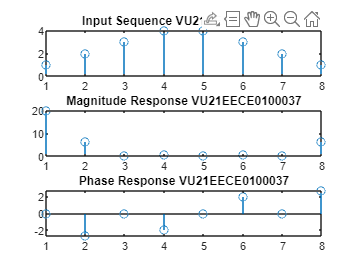


% Plotting
subplot(3,1,1)
stem(abs(x));
title('Input Sequence VU21EECE0100037');

subplot(3,1,2)
stem(abs(y));
title('Magnitude Response VU21EECE0100037');

subplot(3,1,3)
stem(angle(y));
title('Phase Response VU21EECE0100037');